clear all, close all;

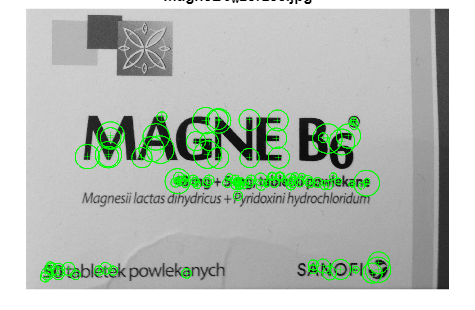

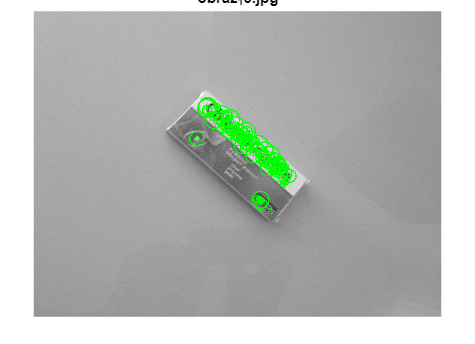

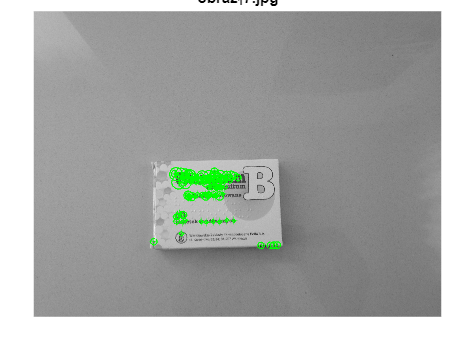

% List of image files
I_files = ["magneB6_wzorzec.jpg", "obraz_13.jpg", "obraz_17.jpg"];

% Loop through each image file
for i = 1:length(I_files)
    I_file = I_files(i); % Get current file name
    I = imread(I_file);  % Read the image
    
    % Convert to grayscale if image is RGB
    if size(I, 3) == 3
        I = rgb2gray(I);
    end
    
    % Detect SURF features
    points = detectSURFFeatures(I);
    
    % Display the image with the strongest features
    figure;
    imshow(I); hold on;
    plot(points.selectStrongest(100)); % Plot the strongest 100 features
    title(['SURF Features: ', I_file]);
end

% Tworzenie tablicy komórkowej z nazwami plików obrazów wzorców
fileNames = {'magneB6_wzorzec.jpg', 'NoSpa_wzorzec.jpg', 'chlorchinaldin_wzorzec.jpg', 'vitaminumB_wzorzec.jpg'};
baza_template
recognition